# 離散フーリエ変換

[⇦ メインメニューに戻る](matlab:open('../MainMenu.mlx'))

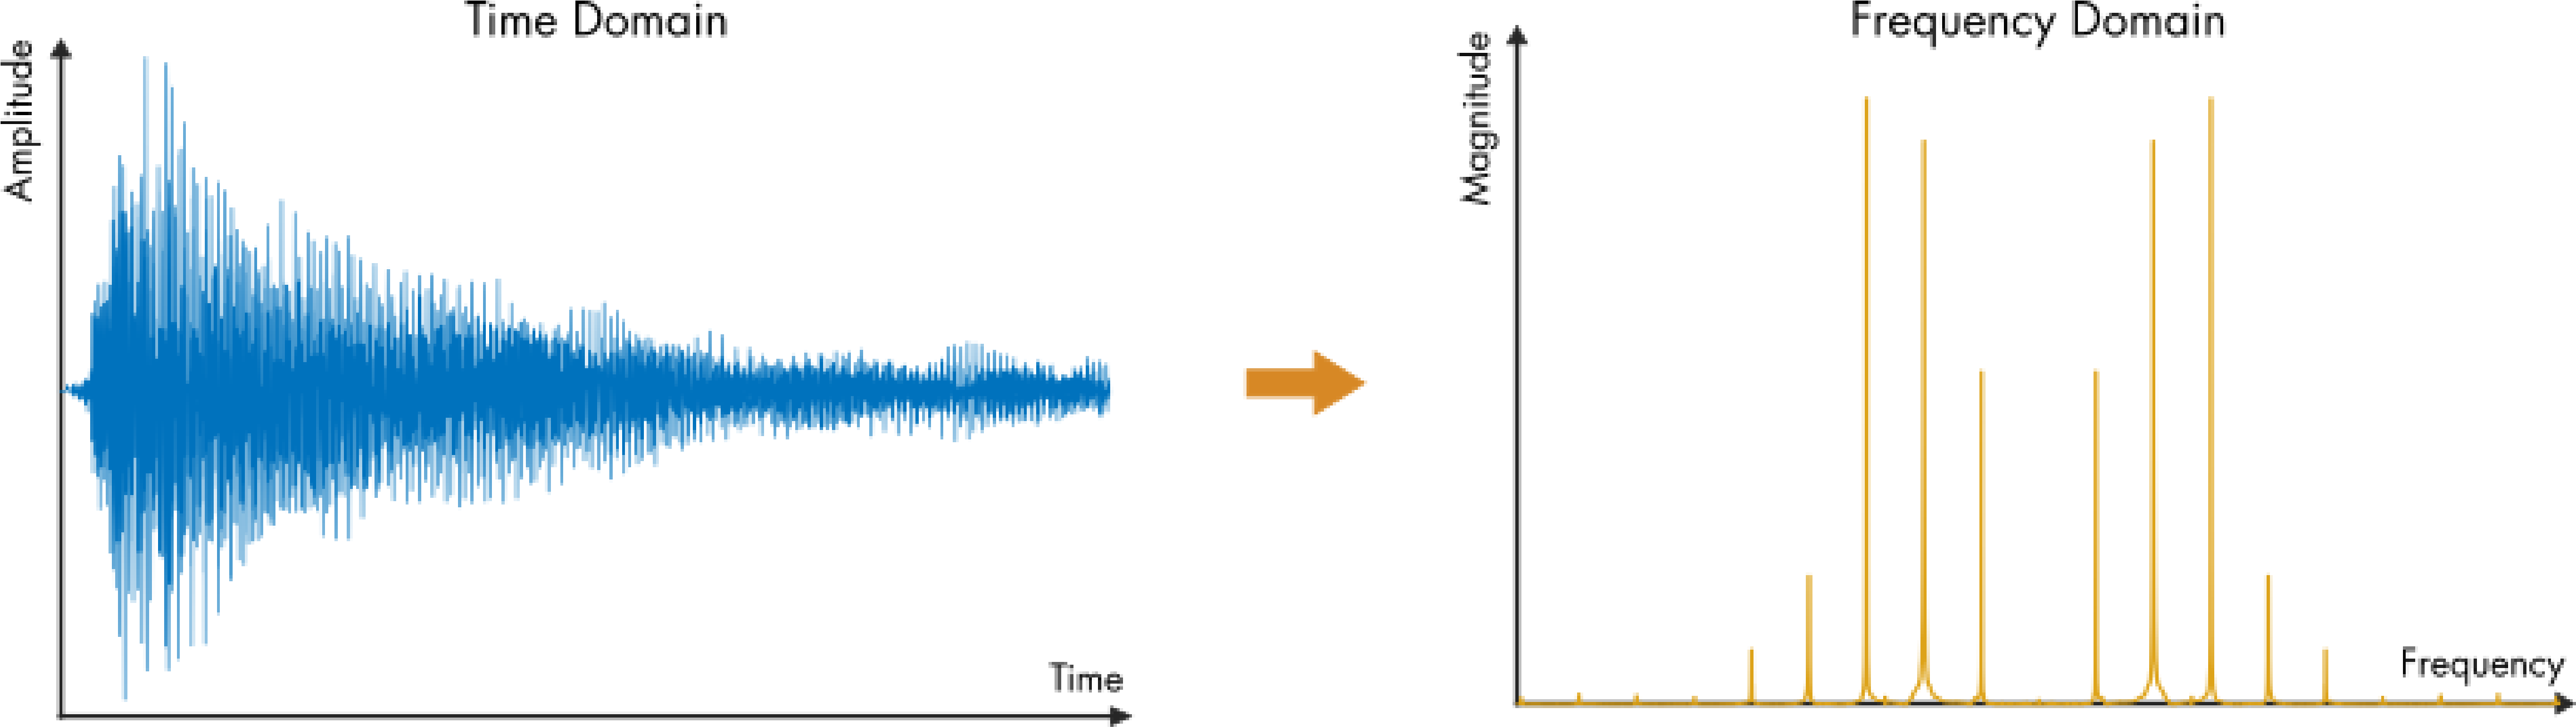

**始める前に：**

このライブスクリプトは、コードが表示され、出力がインラインで表示される状態で使用することを想定しています。MATLABツールストリップの**表示**タブの**表示**セクションで、**インラインで出力**を選択してください。または、ライブエディタウィンドウ右上のアイコン   を使って**インラインで出力**に設定することもできます。

 このライブスクリプトを操作することで、概念やコマンドの理解とともにMATLABに慣れることができます。さらに詳しい説明が必要な場合は、[MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted)（MATLABの基本を学べる無料の2時間オンラインチュートリアル）の受講を検討してください。

   最適な体験のために、指示や手順は示された順番で進めてください。前のセクションを完了してから新しいセクションに進みましょう。いくつかのセクションは前のセクションで作成された変数に依存しており、順番を守らないとエラーが発生します。

   と   のアイコンは、2種類のインタラクティブなアクティビティを示しています。   は、主にこのスクリプトで紹介された概念を、視覚的に理解するインタラクションを紹介します。 のインタラクションは、学習者が概念をどれだけ理解しているかを確認する目的で設計されており、教授による成績評価や完了チェックに使われる場合があります。

## はじめに

フーリエ変換は、解析関数の周波数成分を求めるために使うことができます。

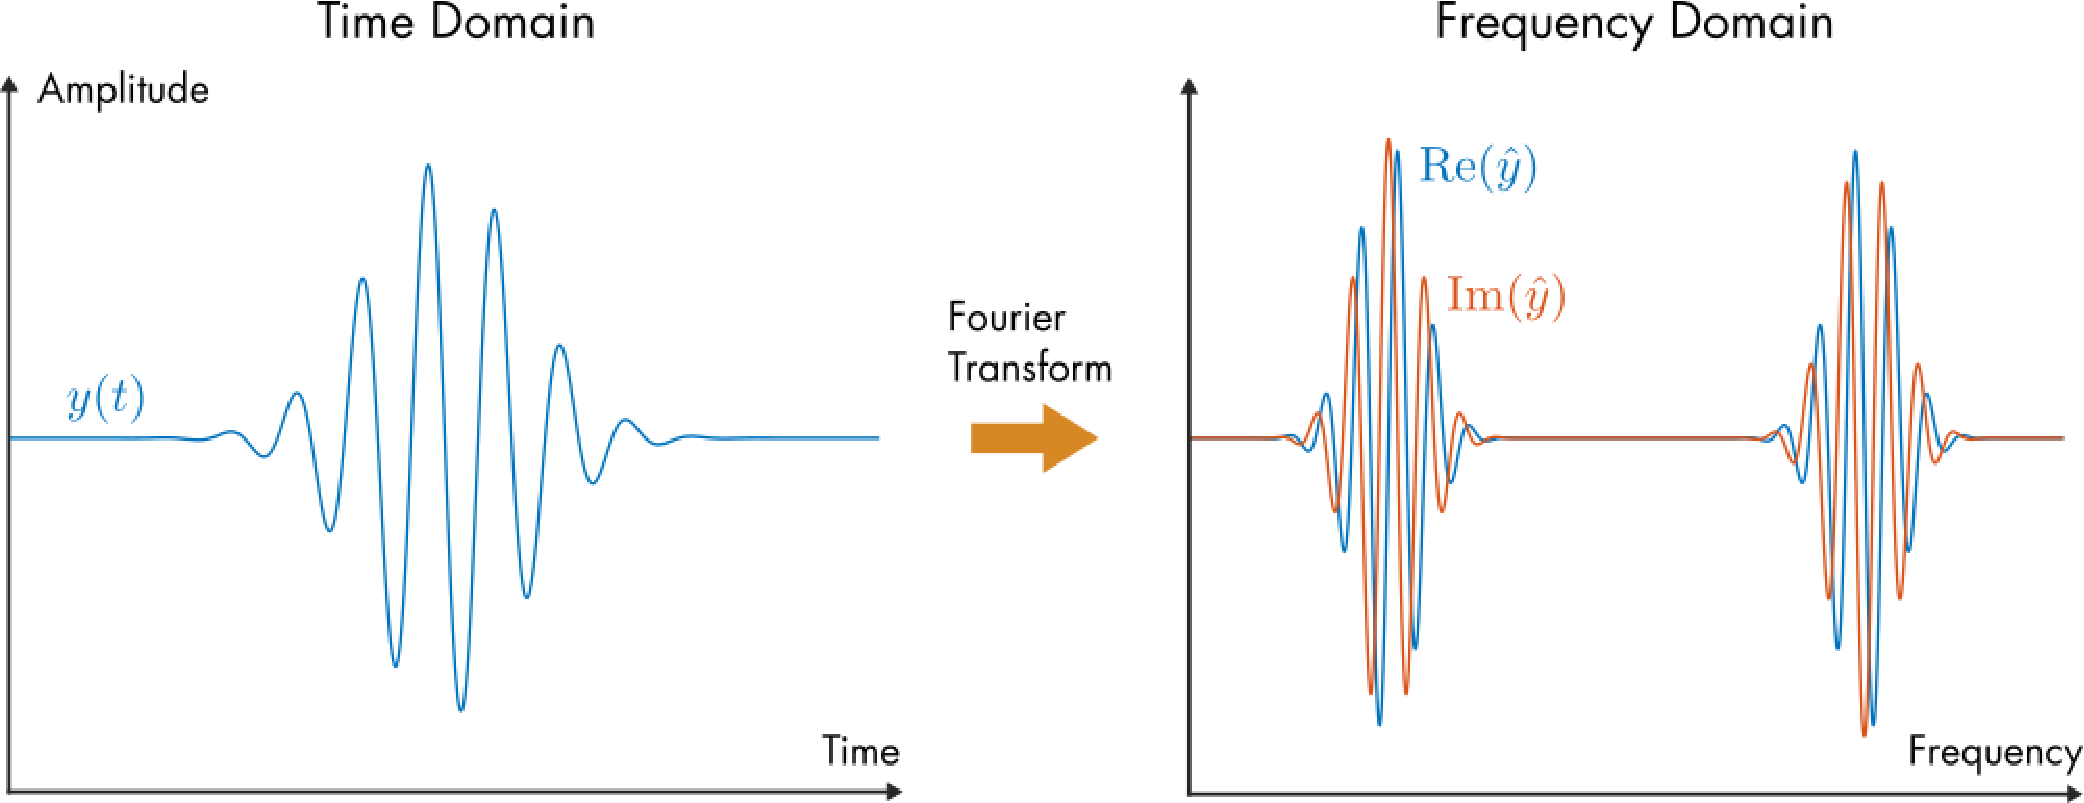

*時間領域と周波数領域におけるガウス変調正弦波。*

しかし、実際の信号は通常、解析関数ではなく、測定値の離散的な列です。このような信号には、フーリエ変換を直接適用することはできません。

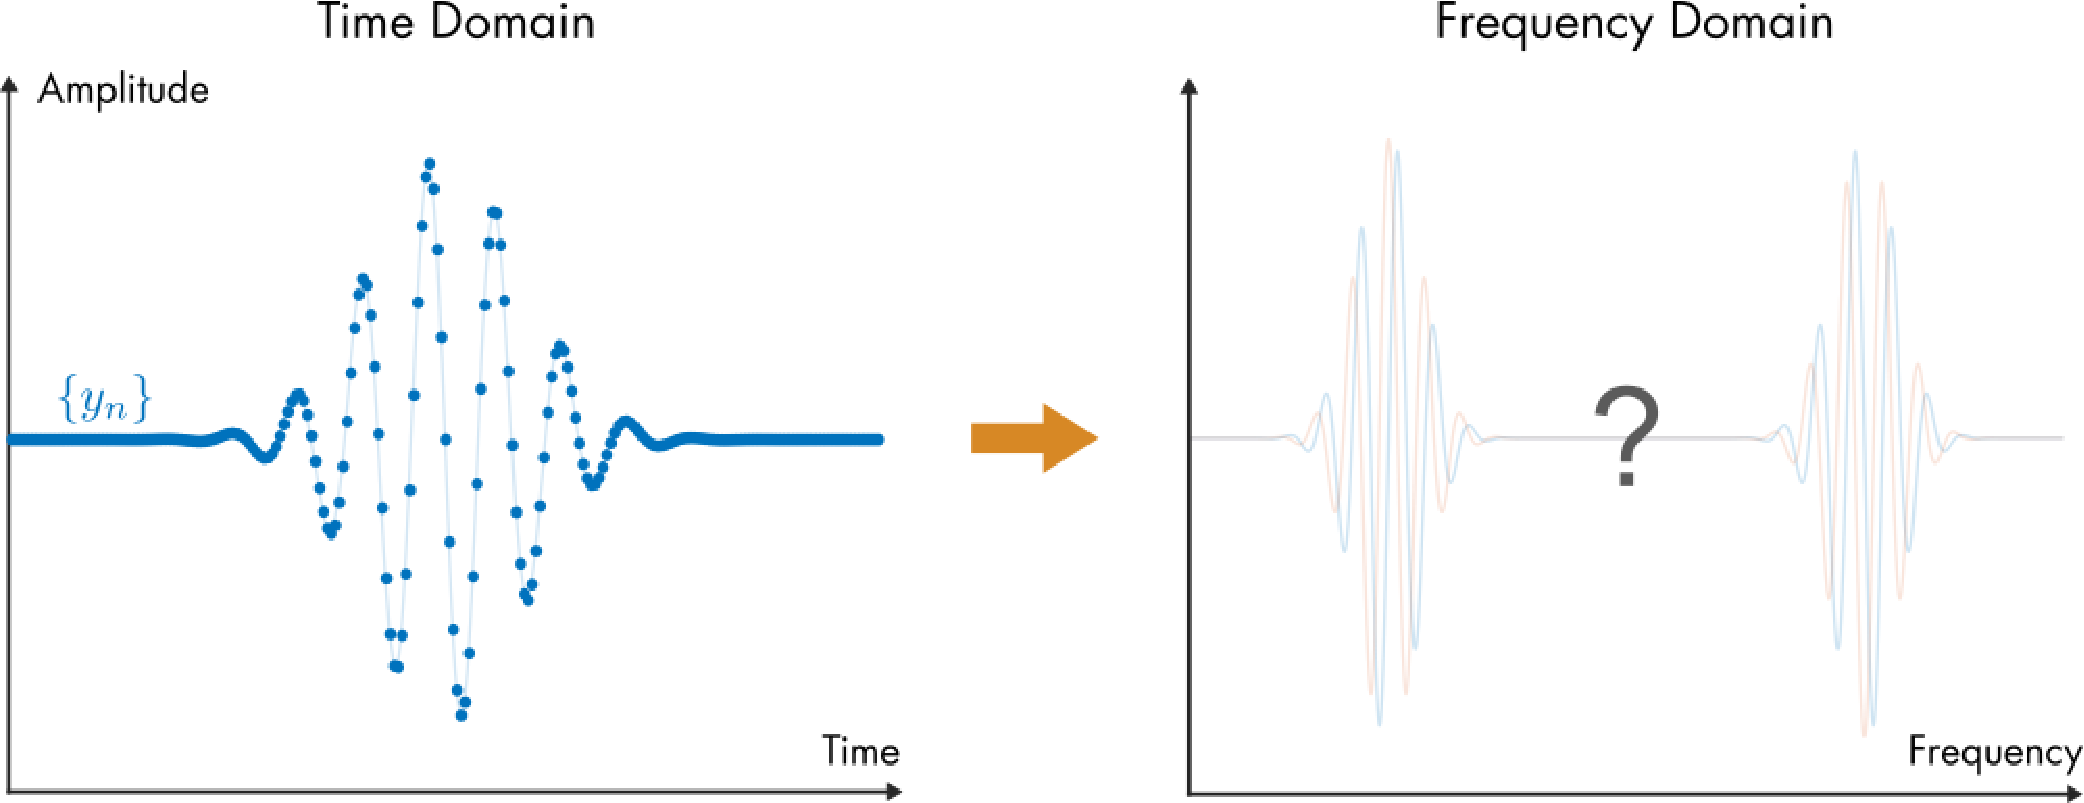

*解析関数からサンプリングされた離散信号* $\{ y_n \}$ *。この信号は周波数領域でどのように見えるでしょうか？*

離散信号を周波数領域で解析するには、*離散フーリエ変換*（DFT）を使うことができます。DFTは、ほとんどの実際の信号が離散的な測定値であるため、おそらく最も広く使われているフーリエ解析ツールです。DFTは別名で呼ばれることも多く、FFT（*高速フーリエ変換*）として知られています。混乱しないでください。両者は本質的に同じものであり、FFTはDFTをより速く計算するアルゴリズムです。

## 定義

DFTは複素フーリエ級数やフーリエ変換と似ています。本質的な違いは、DFTが連続関数を参照せず、完全に離散的な列で動作する点です。DFTは次のように定義されます。


$$Y_k = \sum_{n = 0}^{N-1} y_n e^{- \frac{ 2 \pi i k n }{N }$$


結果は$N$個の離散値$\{ Y_k \}$の列となり、これは周波数領域における$\{ y_n \}$を表します。結果の$\{ Y_k \}$はフーリエ変換$\hat{y}(\omega)$に相当しますが、その詳細は後ほど説明します。

## DFTの計算

 **例.** この例では、合成した音声信号のDFTを定義に従って直接計算します。

**課題.** まず、このセクションを実行してデータ点を作成してください。

  **プロのコツ.** セクションを素早く実行するには、キーボードショートカット**Ctrl**+**Enter**を使いましょう。

[t,y,Fs] = sineGaussData; % Helper function that generates the data

figure
plot(t,y,'.')
xlabel("t (s)")
ylabel("y")

信号を拡大表示して（ズームツール   を使って）、離散データ点 $y_n$ を詳しく観察してみましょう。何かパターンが見えますか？

**課題.** このセクションを実行して、生成された信号をオーディオクリップとして再生してください。

% This code will play the audio signal
soundsc(y,Fs)

**課題.** このセクションを実行して、定義に従ってDFTを計算してください。[`tic`](https://www.mathworks.com/help/matlab/ref/tic.html) および [`toc`](https://www.mathworks.com/help/matlab/ref/toc.html) 関数は、N点DFTの計算にかかる時間を測定するために使われています。

N = numel(y); % The number of samples in y
n = 0:(N-1); % Indices
Y = zeros(N,1);
tic
% Loop through the indices of Yk
for k = 0:(N-1)
    % Compute the sum and put the result in Y
    Y(k+1) = sum( y.*exp(-2*pi*1i*k*n/N) );
end
toc

**課題.** このセクションを実行して、`Y` に格納されたDFTの実部と虚部をプロットしてください。

plot(real(Y),".-")
hold on
plot(imag(Y),".-")
hold off
xlabel("k")
ylabel("Y_k")
% xlim([300 350])

- 信号を拡大表示して、ピーク付近のDFTを見てみましょう。ズームツール ( ) を使うか、`xlim([300 350])` の行のコメントを外しても構いません。

### 高速フーリエ変換（FFT）

前の例では、DFTはforループを使って計算されており、$O(N^2)$の計算量が必要でした。$O(N^2)$という表記は、計算コストがデータ点数$N$の2乗に比例して増加することを意味します。これは、高速フーリエ変換（FFT）と比べて非常に非効率的です。FFTアルゴリズムはDFTをより小さなDFTに分割し、それらの結果を組み合わせて全体のDFTを構成します。FFTは$O(N \log(N))$の演算しか必要としません。つまり、大規模なデータセットではFFTはDFTよりも数千倍速くなることもあります。

 **演習.** この演習では、FFTアルゴリズムを使ってDFTを計算します。

**タスク1.** まず、このセクションを実行してデータ点を作成してください。

[t,y,Fs] = sineGaussData; % Helper function that generates the data

**タスク2.** [`fft`](https://www.mathworks.com/help/matlab/ref/fft.html) 関数を使って `y` のDFTを計算し、その結果を Y に格納してください。

% Write your code here


tic
Y = fft(y);
toc

**タスク3.** **タスク2**の `fft` 関数呼び出しを、[`tic`](https://www.mathworks.com/help/matlab/ref/tic.html) および [`toc`](https://www.mathworks.com/help/matlab/ref/toc.html) コマンドで囲み、FFTの計算にかかる時間を測定してください。前のセクションで定義に従って計算した場合と比べてみましょう。FFTはどれくらい速いですか？

**タスク4.** `Y` の実部と虚部をプロットしてください。実部と虚部を抽出するには、[`real`](https://www.mathworks.com/help/matlab/ref/real.html) および [`imag`](https://www.mathworks.com/help/matlab/ref/imag.html) 関数を使います。同じ座標軸上に描画を続けるには、[`hold`](https://www.mathworks.com/help/matlab/ref/hold.html) コマンドを使ってください。

% Write your code here



正しければ、結果は前の例のDFTプロットと同じになるはずです。

plot(real(Y),".-")
hold on
plot(imag(Y),".-")
hold off
xlabel("k")
ylabel("Y_k")

If correct, your result should be identical to the DFT plot from the previous example.

## DFTとフーリエ変換の比較

ガウス変調正弦波は、解析的な形が既知であるため、DFTとフーリエ変換を比較するのに便利です。おそらく、DFTがガウス変調正弦波のフーリエ変換から予想されるものと似ていることに気づいたでしょう。

前のセクションの離散データ点は、連続関数からサンプリングされたものでした。DFTで何が計算されているのかをよりよく理解するには、元の関数のフーリエ変換を見てみるとよいでしょう。

**課題.** このセクションを実行して、解析的なプロットを表示してください。

plotFourierTransform
% xlim([650 750])
 

 **考察.** 

- DFTのどのピークがフーリエ変換のピークに対応していますか？

- 信号を拡大表示して、ピーク付近のDFTを見てみましょう。ズームツール ( ) を使うか、`xlim([650 750])` の行のコメントを外しても構いません。

- 信号のフーリエ変換はDFTとどのように比較できますか？

フーリエ変換とDFTのプロットの違いを理解するには、DFTとフーリエ変換の定義を比較してみましょう。DFTは次の通りです：


$$Y_k = \sum_{n = 0}^{N-1} y_n e^{- \frac{ 2 \pi i k n }{N }$$


フーリエ変換は次の通りです：


$$\hat{y}(\omega) = \int_{-\infty}^\infty y(t) e^{-i\omega t} \ dt$$


類似点に注目してください：

- DFTの総和は積分を近似しています

- 2つの定義の要素は対応しています $ y_n \leftrightarrow y(t)$ および $e^{- \frac{ 2 \pi i k n }{N }} \leftrightarrow  e^{-i\omega t} $. 

2つの本質的な違いに注目してください：

- 積分の $dt$ はフーリエ変換 $\hat{y}$ をスケーリングしますが、DFTの結果 $Y_k$ は $\Delta t$ でスケーリングされません。

- 複素指数関数は離散的なインデックス $k$ と $n$ で表され、連続変数 $\omega$ と $t$ ではありません。

 **例.** この例では、ガウス変調正弦波を使ってDFTとフーリエ変換の関係を示します。

**課題**. このセクションを実行して、[`fft`](https://www.mathworks.com/help/matlab/ref/fft.html) 関数を使ってDFTを計算してください。

[t,y,Fs] = sineGaussData; % Helper function that generates the data
Y = fft(y);

フーリエ変換は$dt$で（振幅が）スケーリングされます。$dt$の離散的なアナログは、サンプリング信号の時間刻み$\Delta t$です。時間刻み$\Delta t = 1/ f_s$であり、$f_s$はサンプリング周波数です。つまり、出力$Y$を$\hat{y}$に合わせてスケーリングするには、`1/Fs`を掛ければよいことになります。

**課題.** このセクションを実行して`Y`をスケーリングし、その結果をプロットしてください。縦軸のスケールを解析的なフーリエ変換の結果と比較しましょう。

N = length(Y);
k = 0:(N-1);
Yrescaled = 1/Fs*Y;
realImagPlot(k,Yrescaled,"$k$","$\frac{1}{f_s}Y_k$"); % Helper function that creates the plot

サンプリングレート$f_s$を使って、離散的なインデックス$k$や$n$を連続変数$\omega$や$t$に関連付けることもできます。各定義の指数部の項を等しくすると：


$$  \frac{2 \pi kn}{N} = t \omega$$


$t$を$n \Delta t  = n / f_s$として離散化すると、離散周波数は次のようになります


$$\omega_k = \frac{ 2 \pi k f_s}{   N}$$


**課題.** このセクションを実行して、DFTの結果を角周波数$\omega_k$に対してプロットしてください。

omega = 2*pi*k*Fs/N;
realImagPlot(omega,Yrescaled,"$\omega$","$\frac{1}{f_s}Y_k$"); % Helper function that creates the plot

DFTの角周波数（$\omega$軸）とフーリエ変換の角周波数を比較してください。ピークは同じ位置にありますか？グラフ上をクリックしてツールチップを表示することで、ピークの位置を特定できます。

DFTの**最初の**ピークがフーリエ変換の**2番目の**ピークと一致していることに気づくはずです。これはDFTの定義によるもので（予想外の結果をもたらします）、[`fftshift`](https://www.mathworks.com/help/matlab/ref/fftshift.html) 関数を使うことでDFTをフーリエ変換と揃えることができます。

**課題.** このセクションを実行して、DFTの値$\{ Y_k \}$を並べ替え、フーリエ変換$\hat{y}$と揃えてください。$\omega$の値もシフト後の周波数に対応するよう再生成されます。

% Shift the Y-values
Yshift = fftshift(Yrescaled);
% Shift the angular frequency
omegaShift = 2*pi*Fs/N*(-N/2:N/2-1);

realImagPlot(omegaShift,Yshift,"$\omega$","$\frac{1}{f_s}Y_k$"); % Helper function that creates the plot
xlim([-1000 1000])

**課題.** このセクションを実行して、シフトしたDFTの値（`Yshift`）とフーリエ変換を並べてプロットしてください。

plotDFTandTransform(omegaShift,Yshift);
% xlim([650,750])

- 信号を拡大表示して、ピーク付近のDFTを見てみましょう。ズームツール ( ) を使うか、`xlim([650,750])` の行のコメントを外しても構いません。

## オーディオ信号の解析

FFTは、計測信号の周波数領域の内容を解析するためによく使われます。これは信号処理における基本的な手法の一つです。

 **演習.** この演習では、ギターの音に含まれる周波数を解析します。

**タスク1.** このセクションを実行してMP3を読み込み、信号をプロットしてください。信号の内容は`g`に格納されています。

% This code plays the guitar sound and plots part of the signal
[g2Ch,Fs] = audioread("Anote.mp3");
g = g2Ch(:,1); % Only use the first audio channel
soundsc(g,Fs)
plotGuitarSignal(g,Fs)

- 信号を拡大表示して、時間領域の内容を見てみましょう ( )。

**タスク2.** [`fft`](https://www.mathworks.com/help/matlab/ref/fft.html) を使って信号`g`のDFTを計算してください。結果は`G`に格納してください。

% Write your code here


G = fft(g);

**タスク3.** `G`に`1/Fs`（`Fs`はサンプリング周波数）を掛けてスケーリングしてください。これにより、`G`の縦軸がフーリエ変換と対応します。結果は`Gscaled`に格納してください。

% Write your code here


Gscaled = G*1/Fs;

**タスク4.** FFTの結果は、「高周波成分」を負の周波数側にシフトした後の方がより意味があります。[`fftshift`](https://www.mathworks.com/help/matlab/ref/fftshift.html) を使ってこの操作を`Gscaled`に対して行い、結果を`Gshift`に格納してください。

% Write your code here


Gshift = fftshift(Gscaled);

**タスク5.** `GShift`に対応する角周波数を計算し、ベクトル`omega`に格納してください。`fftshift`の結果に対応する角周波数（rad/s）は


$$\omega_k = \frac{ 2 \pi k f_s}{   N}$$
 

ここで、$f_s$はサンプリング周波数、$N$はサンプル数、$k$は$-N/2$から$N/2-1$までの範囲です。

**ヒント**: まず信号`g`の長さを計算し、その結果を`N`に格納してください。サンプリング周波数はすでに変数`Fs`に格納されています。

% Write your code here


N = numel(g);
omega = 2*pi*Fs/N*(-N/2:N/2-1);

**タスク6.** `Gshift`の実部と虚部を`omega`に対してプロットしてください。

**ヒント**: 実部と虚部を抽出するには、[`real`](https://www.mathworks.com/help/matlab/ref/real.html) および [`imag`](https://www.mathworks.com/help/matlab/ref/imag.html) 関数を使ってください。同じ座標軸上に描画を続けるには、[`hold`](https://www.mathworks.com/help/matlab/ref/hold.html) コマンドを使いましょう。

figure % Create a new figure
% Write your code here


plot(omega,real(Gshift))
hold on
plot(omega,imag(Gshift))
hold off
xlim([-1e4 1e4])
xlabel("$\omega$","Interpreter","latex")
ylabel("$\hat{g}$","Interpreter","latex")

ズームツール( )や[`xlim`](https://www.mathworks.com/help/matlab/ref/xlim.html)を使ってプロットを拡大してください。計算が正しければ、次のようなプロットが表示されるはずです。

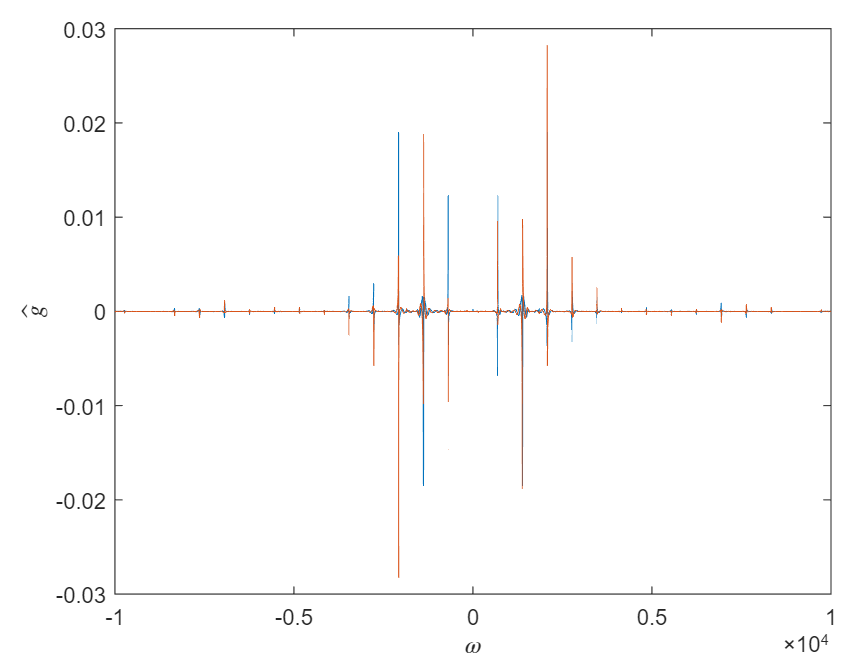

$G$の実部や虚部を見る代わりに、絶対値（振幅）を見る方がより有用な場合が多いです。

**タスク7.** [`abs`](https://www.mathworks.com/help/matlab/ref/abs.html)を使って`Gshift`の絶対値を計算してください。結果は`Gabs`に格納してください。その後、`Gabs`を`omega`に対してプロットしてください。

% Write your code here
Gabs = abs(Gshift);
plot(omega,Gabs)
xlabel("$\omega$","Interpreter","latex")
ylabel("$|\hat{g}|$","Interpreter","latex")

**タスク8.** 角周波数$\omega$（rad/s単位）でプロットするのはフーリエ変換との比較には便利ですが、実際の信号を理解するにはあまり役立ちません。

- `omega`からHz単位の周波数を計算し、結果を`freq`に格納してください。

- `Gabs`を`freq`に対してプロットしてください。

- 多くの周波数成分は-1kHzから1kHzの間にあるので、軸の範囲をその範囲に調整してください。

% Write your code here


freq = omega/(2*pi);
plot(freq,Gabs)
xlabel("f (Hz)")
ylabel("|g|")
xlim([-1000 1000])

**タスク9.** この信号はギターの1本の弦を弾いたものです。どの弦（ローE、A、D、G、B、ハイE）からの音でしょうか？下のスペースに答えを記入してください。

**ヒント:**

- 1本の弦は基本周波数といくつかの倍音で振動します。

- 周波数領域でピークをクリックするとツールチップが表示されます。

- 関連する音階の表が下に示されています。

 
$$\text{\textbf{オクターブ2}}
\\
\begin{array}{lr} 
\text{音} & \text{ Hz} \\
C & 65.4 \\ 
C\# & 69.3 \\
D & 73.4 \\
D\# & 77.8\\
E & 82.4\\
F & 87.3 \\
F\# & 92.5 \\
G & 98.0\\
G\# & 103.8\\
A & 110.0\\
A\# & 116.5\\
B & 123.5\\
\end{array}$$
 
$$\text{\textbf{オクターブ3}}
\\
\begin{array}{lr} 
\text{音} & \text{ Hz} \\
C & 130.8 \\ 
C\# & 138.6 \\
D & 146.8\\
D\# & 155.6\\
E & 164.8\\
F & 174.6 \\
F\# & 185.0 \\
G & 196.0\\
G\# & 207.7\\
A & 220.0\\
A\# & 233.1\\
B & 246.9\\
\end{array}$$
 
$$\text{\textbf{オクターブ4}}
\\
\begin{array}{lr} 
\text{音} & \text{ Hz} \\
C & 261.6 \\ 
C\# & 277.2 \\
D & 293.7\\
D\# & 311.1\\
E & 329.6\\
F & 349.2\\
F\# & 370.0\\
G & 392.0\\
G\# & 415.3\\
A & 440.0\\
A\# & 466.2\\
B & 493.9\\
\end{array}$$


% Record your answer (E, A, D, G, or B) in the quotes
note = "A";

[⇦ メインメニューに戻る](matlab:open('../MainMenu.mlx'))

**補助関数**

function [t,y,Fs,A,c,t0,omega0,tLims,N] = sineGaussData
    % Sample a Gaussian-modulated sinusoid

    Fs = 2e3; % Audio sample rate

    % Gaussian-modulated sine data
    A = 1.5; % Amplitude
    f0 = 110; % Carrier frequency (Hz)
    c = 0.3; % Gaussian "width"
    t0 = 1; % Center position (s)
    omega0 = f0*2*pi; % Angular frequency (rad/s)

    % Discretize
    tLims = [0 3];
    N = round(Fs*(tLims(2)-tLims(1)));
    t = (0:1/Fs:N/Fs-1/Fs) + tLims(1);
    y = A*sin(omega0*t).*exp(-(t-t0).^2/(2*c^2));
end

function plotFourierTransform
    % Plot the Fourier transform of the Gaussian-modulated sinusoid

    % The function data
    [t,y,Fs,A,c,t0,omega0,tLims,N] = sineGaussData;

    % Plot parameters
    omegaLims = 2*pi*[-150 150];

    % Compute transform
    omega = linspace(omegaLims(1),omegaLims(2),2e4);
    yhat = -A*sqrt(pi/2)*1i*c.*(exp(-0.5*(omega-omega0).*(c^2*omega-c^2*omega0+2*t0*1i)) - ...
        exp(-0.5*(omega+omega0).*(c^2*omega+c^2*omega0+2*t0*1i)));

    % Create plots
    figure("Position",[1 1 800 400])
    subplot(1,2,1)
    plot(t,y)
    xlim(tLims)
    xlabel("$t$","Interpreter","latex")
    ylabel("$y$","Interpreter","latex")
    title("Time Domain","Interpreter","latex")

    subplot(1,2,2)
    plot(omega,real(yhat))
    hold on
    plot(omega,imag(yhat))
    hold off
    xlim([omega(1),omega(end)])
    xlabel("$\omega$ (rad/s)","Interpreter","latex")
    ylabel("$\hat{y}$","Interpreter","latex")
    legend("Re$(\hat{y})$","Im$(\hat{y})$","Interpreter","latex","Location","south");
    title("Frequency Domain","Interpreter","latex")

end

function realImagPlot(x,y,xLabel,yLabel)
    % Create complex plot with the given labels
    
    figure
    plot(x,real(y),".-")
    hold on
    plot(x,imag(y),".-")
    hold off
    xlabel(xLabel,"Interpreter","latex")
    ylabel(yLabel,"Interpreter","latex")
end


function plotDFTandTransform(omegaShift, Yshift)
    % Plot the DFT in Yshift and the Fourier 
    % transform of the Gaussian-modulated sinusoid
    
    colors = lines(2);

    % Plot the DFT
    figure
    plot(omegaShift,real(Yshift),".","MarkerSize",8)
    hold on
    plot(omegaShift,imag(Yshift),".","MarkerSize",8)
    hold off

    % Compute transform and plot it
    [t,y,Fs,A,c,t0,omega0,tLims,N] = sineGaussData;
    % Plot parameters
    omegaLims = 2*pi*[-150 150];
    % Compute transform
    omega = linspace(omegaLims(1),omegaLims(2),2e4);
    yhat = -A*sqrt(pi/2)*1i*c.*(exp(-0.5*(omega-omega0).*(c^2*omega-c^2*omega0+2*t0*1i)) - ...
        exp(-0.5*(omega+omega0).*(c^2*omega+c^2*omega0+2*t0*1i)));
    
    hold on
    plot(omega,real(yhat),"color",colors(1,:)*0.75)
    plot(omega,imag(yhat),"color",colors(2,:)*0.75)
    hold off
    xlim([omega(1),omega(end)])
    xlabel("$\omega$ (rad/s)","Interpreter","latex")
    ylabel("$\hat{y}$","Interpreter","latex")
    legend("Re$(Y_k)$","Im$(Y_k)$",...
           "Re$(\hat{y})$","Im$(\hat{y})$",...
           "Interpreter","latex","Location","eastoutside");
    title("Frequency Domain","Interpreter","latex")
end


function plotGuitarSignal(yGuitar,FsGuitar)
    % Plot the guitar signal in the time domain

    tGuitar = (1:length(yGuitar))/FsGuitar; % Time variable    
    % Generate the plot
    figure("position",[1,1,800,400]) 
    plot(tGuitar,yGuitar(:,1),"Linewidth",1)
    xlabel("$t$ (s)","Interpreter","latex")
    ylabel("$g$","Interpreter","latex")
    title("Time domain","Interpreter","latex")
end

% Unused suggestions
%#ok<*ASGLU>